# MATLAB Section 3: Collecting and Managing Data

## Part 1: What is an API?

In the beginning of this lesson, APIs are described as mechanisms that allow 2 software components to communicate with each other using a set of definitions and protocols. A useful metaphor to understand APIs is thinking of them a messenger, similar to how a waiter communicates your order to the kitchen. Applications of APIs in daily life include ride-share apps, airline websites, and apps that allow you to control devices, like a thermostat. All of these apps send data to a server so that it can perform a series of actions to fulfill your request. 

### **Modern APIs & Benefits**

The most widely used and flexible APIs are known as Representational State Transfer (REST) APIs. In REST APIs, a server uses input from the client to perform internal functions and return output data. Data is encoded and transported between the clients and servers using Hypertext Transfer Protocol (HTTP). The main benefits of REST APIs are integration and ease of maintenance. REST APIs allow existing software systems to be integrated to new applications without having to make changes to the code of the two systems. Another important feature of APIs are endpoints. API endpoints include server URLs, services, and other digital locations from where information is sent and received between systems

### **Scope of API Use**

- Private API: Used only for connecting systems and transporting data within a single business.

- Public API: Open to the public but may have some authorization restrictions associated with them. 

- Partner API: Available only to authorized developers to facilitate business-to-business partnerships.

- Composite API: A combination of two or more of the types above to meet complex system requirements.

### REST API Security

REST APIs are secured using authentication tokens and API keys. Authentication tokens authorize users to make a specific API call and verify the user's identity before processing an API call. API keys verify the program or app making the API call to ensure it has the permission to make a specific call. API keys allow API monitoring to gather data on usage. API keys appear in browser URLs as a long string of characters and numbers and are used by the website to make internal API calls. 

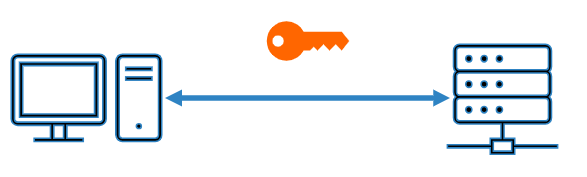

## Part 2: Accessing an API - Spotify

In this section, we will be accessing the Spotify API to gather music data. To get started you will need to create a Spotify developer account. 

[**Please watch this video**](https://youtu.be/ute70c0Rvng)** on how to create a Spotify developer account and get the client information to access the API.**

Spotify Developer Link: [Web API | Spotify for Developers](https://developer.spotify.com/documentation/web-api)

Create a Spotify Developer account or log in with your Spotify account. Once you have access, go to the developer dashboard to create a "Web API". While creating the app, you will be asked to create a redirect URI. The redirect URI should have the following format "http://localhost:8081". Any combination of numbers is valid. After the app is created retrieve your unique client ID and client secret by accessing the app's credentials in the settings. You will use these to run the code provided below. 

The functionalities of the Spotify Web API include:

- Retrieving data from an artists, album, or shows

- Searching for Spotify content

- Getting recommendations based on the music you listen to

Before retrieving any data, we need to first get an access token using your client ID and client secret. 

clientID = 'YOUR ID'; % Replace with your actual client ID
clientSecret = 'YOUR ID'; % Replace with your actual client secret

% Create the URL for token retrieval
url = 'https://accounts.spotify.com/api/token';

% Encode the client ID and client secret in base64
authString = matlab.net.base64encode([clientID ':' clientSecret]);

% Set the options for the HTTP request
options = weboptions('RequestMethod', 'post', 'MediaType', ...
    'application/x-www-form-urlencoded', 'HeaderFields', {'Authorization', ['Basic ' authString]});

% Set the POST data
postData = 'grant_type=client_credentials';

% Make the POST request to retrieve the access token
response = webwrite(url, postData, options);

% Extract the access token from the response
Token = response.access_token;

% Display the access token (you can process it further as needed)
disp(['Access Token: ' Token]);
 

Now that we have an access token we can start retrieving data. In the example below we will retrieve data from four Artists: Kendrick Lamar, Drake, Taylor Swift, and Billie Eilish. First ,we need to construct the URL for each of their Spotify profiles using their Spotify IDs. The Spotify ID is a unique string of characters used to identify an artist on Spotify.  

Here's how to find it: 

- Go to the Artist's Page on Spotify and click on the 3 horizontal dots below the artist's name.

- Select Share from the menu and click Copy link to artist.

- Paste this link into a browser.

- The Spotify ID is the string of characters located between /artist/ and ?

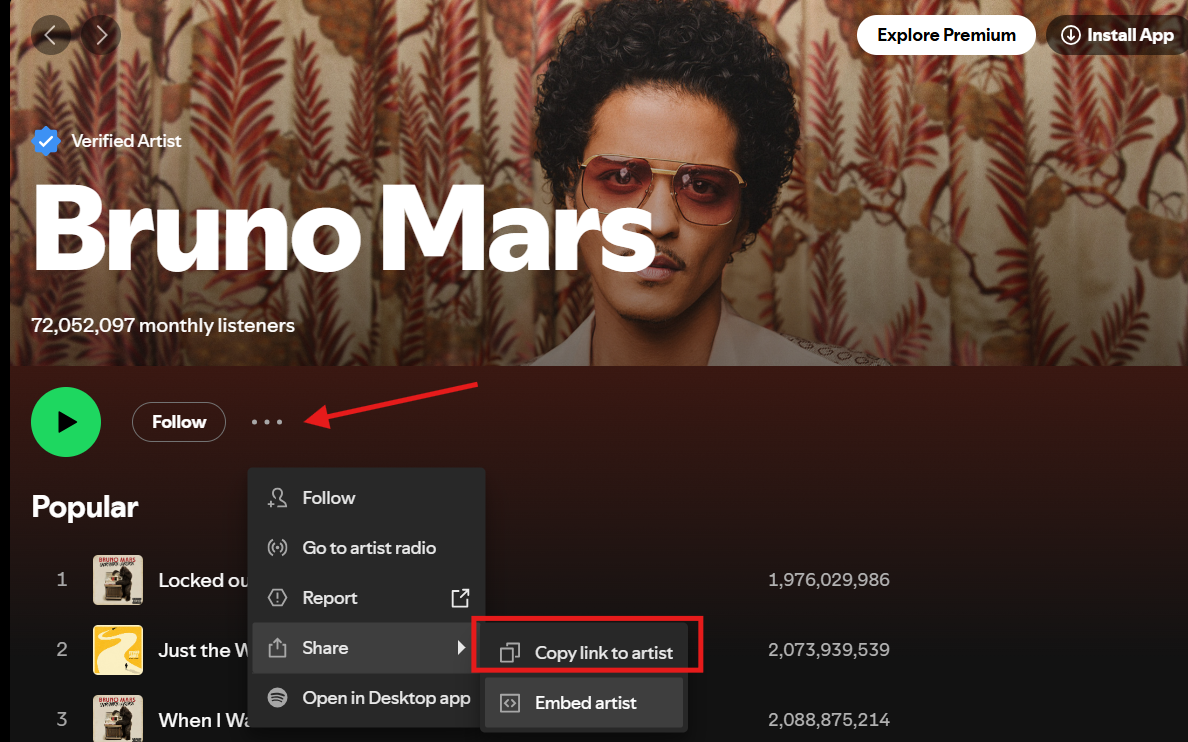

For more details on how to get Spotify IDs: [How do I find my Spotify ID? | Ditto Music Support](https://support.dittomusic.com/en/articles/6701098-how-do-i-find-my-spotify-id)

If you don't have access to Spotify you can instead Google search the artist's ID and right click to copy the link address to their Spotify page. Paste their link into the MATLAB live script and delete everything except their Spotify ID. 

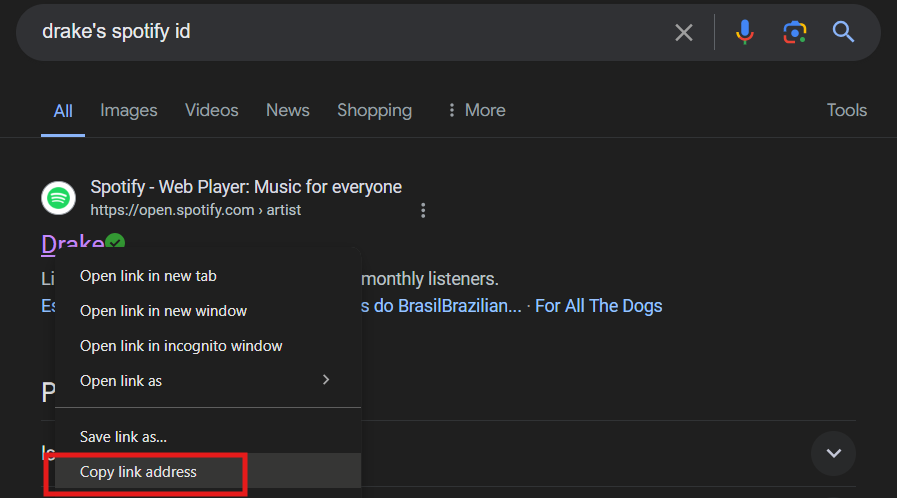

Here is the link to Drake's Spotify page, which includes his Spotify ID in bold at the end of the link: https://open.spotify.com/artist/**3TVXtAsR1Inumwj472S9r4**

Once you have all four IDs you need to stored them into a variable as shown below. 

% Spotify Artist IDs for Drake, Lamar, Swift, and Eilish, respectively
% It is important to separate each ID using commas. 
artistIDs = '3TVXtAsR1Inumwj472S9r4,2YZyLoL8N0Wb9xBt1NhZWg,06HL4z0CvFAxyc27GXpf02,6qqNVTkY8uBg9cP3Jd7DAH';
 

Now that we have all the IDs we will create a URL and read it with the function **webread()** to retrieve each artists' Spotify profile. The endpoint used in the code below is '`https://api.spotify.com/v1/artists?ids=`'.

You can explore other endpoints in  the Reference section of the Spotify Developers website: [Web API Reference | Spotify for Developers](https://developer.spotify.com/documentation/web-api/reference/get-an-albums-tracks). The website has the interactive feature shown below that can help you create the URL you desire. You will use this feature in a later activity and it could come in handy when looking for data for your AI model project. 

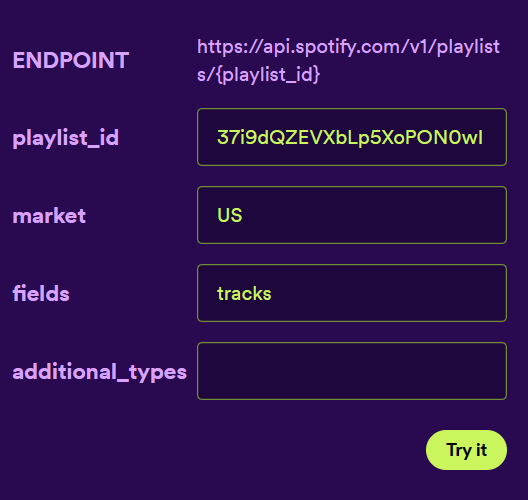

% Create the URL for top tracks
url = 'https://api.spotify.com/v1/artists?ids=';
url = strcat(url, artistIDs);
disp(url)

% Set the options for the HTTP request
options = weboptions('HeaderFields', {'Authorization', ['Bearer ' Token]});

% Make the GET request
response = webread(url, options);
 

To see what data was retrieved, we can click on the variable "response" stored in the workspace. Then click "artists". 

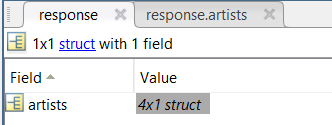

Below is the data retrieved. Here we can see the artists' popularity indices, which is a number out of 100 that Spotify uses to rank artists based on the popularity of their music. There is also information about their followers and genres of their songs. 

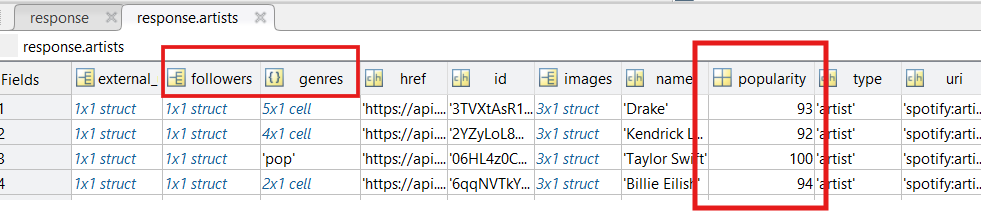

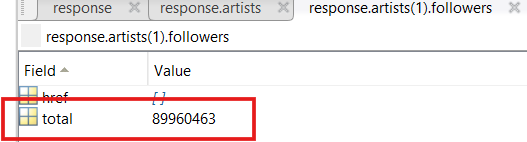

The code below uses the data from the Spotify to create a bar graph showing how many followers each artists has on Spotify. We will be using a for loop and dot notation to retrieve the number of followers for each artists from the variable response.

% Create a vector with four zeros to 
% store the number of followers of each artist
followers = [0 0 0 0];

% Use a for loop with 4 iterations to get the 
% number of followers of each artist
for ii=1:4
    followers(ii) = response.artists(ii).followers.total;
end
 

Now let's make a bar graph to visualize which artist has the most followers. 

% Create a variable for the artists names
Artists = ["Drake" "Lamar" "Swift" "Eilish"];

% Create a bar graph with the data
b=bar(Artists, followers,"blue");

% Add a title and axis titles
title("Spotify Followers")
ylabel("Followers")
xlabel("Artist")

% Makes y-axis label increase by intervals of 
% 10 million all the way to 120 million
yticks(0:10e6:120e6)
% Makes grid lines on the graph
grid on

 


**Now You Try!** Create a bar graph using the code to compare the popularity index of each artist.

*Hint: Use a for loop and the dot notation response.artists(i).popularity to retrieve the data needed.*

% Create a vector with four zeros to store the popularity index of each artist

Popularity = [0 0 0 0];

% Use a for loop with 4 iterations to get the popularity indices for
for i=1:4
    Popularity(i) = response.artists(i).popularity;
end

% Input the variables for the x-axis and y-axis
bar(Artists, Popularity, "green")

% Create a title and label the axes
title("Popularity on Spotify")
ylabel("Popularity Index")
xlabel("Artist")

% Make the y-axis increase by intervals of 5 from 0 to 100
yticks(0:5:100)

% Make a grid lines on the graph
grid on
 

**Discussion**

Look at the graphs we just made:What do the graphs reveal about the artists? Is their popularity directly related to the number followers they have? How does this affect decision making when making AI model to find out go is the next GOAT?

## Part 3: Storing and Sorting Data

Now that we are able to access large amounts of data we need to find a way to store it properly. In the following example, we will reuse the Formula 1 files from section 2 to demonstrate how to create a datastore in MATLAB and sort data. 

### **Datastores**

A datastore provides a convenient way to access data stored in multiple files. When making a datastore we provide the location of the data, so MATLAB can look at all the data files in that location and return a variable with information about the files. The benefit of a datastore is that we can manage a large collection of files containing data too large to fit in the system's memory. 

The table below includes the functions required to make a specific datastore type.

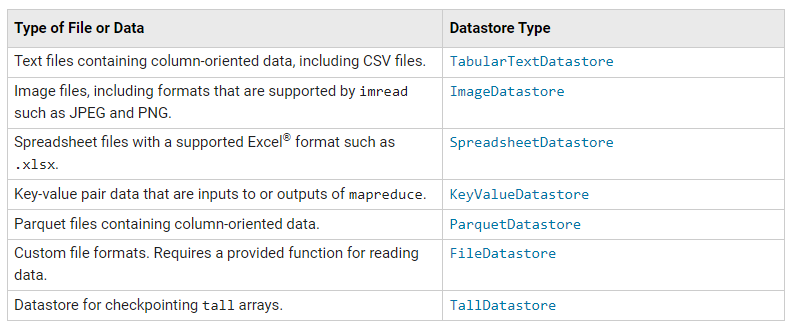

The segment of code below searches for files with the words "F1Results.csv" in their name using the function **tabularTextDatastore(). **To facilitate the creation of the datastore we can put all the files in the same folder as this live script. However, this is not required since we can specify the location of the files within the function.

*Recommendation*: *You can use "copy path" by right clicking on the file to get the .csv path for the  tabularTextDatastore() function*

% Clear the command window and workspace
clc; clear;

% Creates a datastore with all the files with "*F1Results" in their name.
% First Copy the file path into the function tabularTextDatastore(), 
% then replace the year 2019 with *. Now the function will find all the F1
% results files.
ResultsDS = tabularTextDatastore("/MATLAB Drive/MATLAB_Section03_V2/*F1Results.csv")
 

By examining the output we can see that 3 files containing F1 results have been stored in the datastore.

**Now You Try!**

To access the files store in the newly created datastore, we can use the **read() **function.This function will call each file in the datastore one at a time. The first time we use **read(), **data from the first file is imported. Using it a second imports data from the second file, and so on. Click the run button 3 times to see how the data table changes. What happens when you click the run button a 4th time?

% To make the line of code work, type ResultsDS into the input of the
% read() function. Then click the run button 4 times.
files = read(ResultsDS)
% If you try to use read() a fourth time, an error message will appear 
% because there are only 3 files in the datastore. 
 

Let's reset the datastore using **reset()** and use **read()** 3 times to store each file in the datastore into its own variable. 

% Resets the datastore to allow rereading of the data
reset(ResultsDS);

% Uses the read function to store each file in ResultsDS into separate variables
Race2012 = read(ResultsDS);
Race2016 = read(ResultsDS);
Race2019 = read(ResultsDS);
 

### **Sorting Data**

Now that we have all three data tables in our workspace, we will explore two functionalities of data tables in MATLAB: sorting data and adding data. Being able to quickly sort data is very helpful when providing data to an AI model. For this example, we will first call the 2012 race results and then sort the driver number column from least to greatest. 

% This line calls the 2012 race results and store them into a variable
call = Race2012 

 

When we hover over the headings of each column a drop down arrow appears. This arrow allows us to sort the data from smallest to largest or vice versa.  

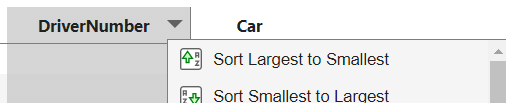

Notice that after selecting one of these options, MATLAB will provide the code necessary to implement these changes into the live script. This is a very useful feature, especially when making modifications to plots.

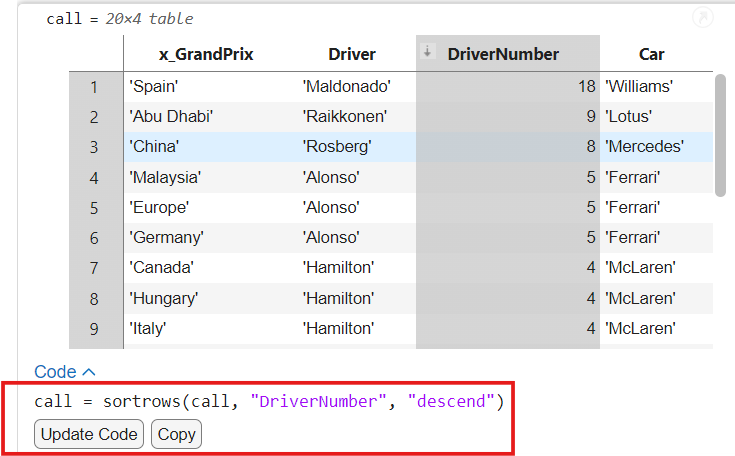

**Now You Try!**

Go back to the data table above and follow the steps to sort the DriverNumber column. Then click "Update Code" or "Copy" to incorporate the suggested code to the live script and rerun this section. When you sorted the DriverNumber column, did the other columns also change?

Another important feature is the ability to add columns to an existing data table. Adding columns to a table can be a useful way of storing the results of calculations performed on a dataset. 

The example below adds an extra column of data to the 2012 race results using dot notation. The additional column will contain the number of laps in a race. 

% Adds a column called "Laps" using dot notation and the transpose of a row vector.
% The transpose is represented with an apostrophe ' and makes the row
% vector into a column vector.
call.Laps = [58 56 56 57 66 78 70 57 52 67 69 44 53 59 53 55 60 55 56 71]'
 

### Missing Data

Finally, let's review what can be done when the data you have has missing values. When files with missing values are imported into MATLAB, the missing data is often replaced with NaN (Not a Number). Any calculations involving NaN will result in a value of NaN and can create misleading computations. The image below shows some functions that are commonly used to deal with missing data values. 

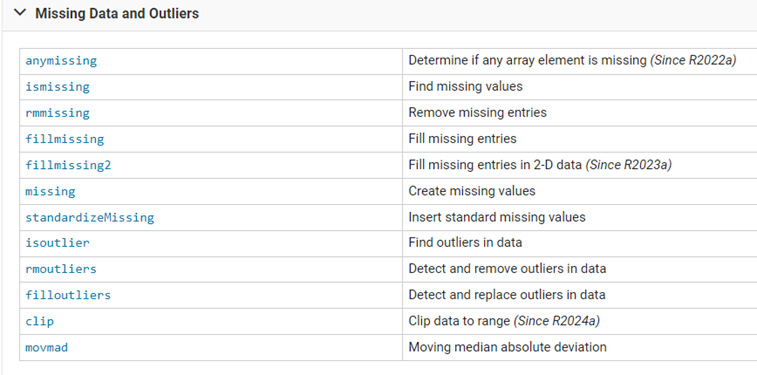

In the example below, we will first create a data table of imaginary release dates from five artists. The data table will purposefully contain missing information that we can use to exemplify how to handle missing data. 

% creates a number list with a missing value
Numbers = [missing 1 2 3 4 5];

% creates a list of dates for five months
Dates = [missing datetime(2024,1:5,1)];

% creates a list of artists' names
Names = [missing "Drake" "Kendrick Lamar" "Taylor Swift" "Billie Eilish" "Bad Bunny"];

% creates missing categorical data
xCategorical = [missing categorical({'One Dance' 'Not Like Us' 'Cruel Summer' ...
    'What Was I Made For?' 'Monaco'})];

% creates the table 
Table = table(Numbers',Dates',Names',xCategorical')

Table = 6×4 table
    Var1       Var2              Var3                  Var4        
    ____    ___________    ________________    ____________________

    NaN             NaT    <missing>           <undefined>         
      1     01-Jan-2024    "Drake"             One Dance           
      2     01-Feb-2024    "Kendrick Lamar"    Not Like Us         
      3     01-Mar-2024    "Taylor Swift"      Cruel Summer        
      4     01-Apr-2024    "Billie Eilish"     What Was I Made For?
      5     01-May-2024    "Bad Bunny"         Monaco              


We can use **ismissing() **to find where data is missing in the table. The function will output a logical array with ones in the positions where data is missing.

% Creates a logical array to see where data is missing
Positions = ismissing(Table)

Positions = 6×4 logical array
   1   1   1   1
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


This function is very helpful because you do not have to go row by row to find where data is missing. Knowing the  location of missing data is the first step in cleaning your data. 

With the function **rmmissing() **we can remove all missing data types. The benefit of this function is that it works with any kind of data type. In our example, this function works perfectly because all the missing data is in the same row, so that row is removed entirely. However, missing data is not always in the same row, so instead we end up with blank spaces randomly throughout your data table. 

% Removes all missing data types
CleanTable = rmmissing(Table)

CleanTable = 5×4 table
    Var1       Var2              Var3                  Var4        
    ____    ___________    ________________    ____________________

     1      01-Jan-2024    "Drake"             One Dance           
     2      01-Feb-2024    "Kendrick Lamar"    Not Like Us         
     3      01-Mar-2024    "Taylor Swift"      Cruel Summer        
     4      01-Apr-2024    "Billie Eilish"     What Was I Made For?
     5      01-May-2024    "Bad Bunny"         Monaco              


Finally, it is important to note that many MATLAB functions enable you to ignore missing values, without having to explicitly locate, fill, or remove them first. For example, if you compute the sum of a vector containing `NaN` values, the result is `NaN`. However, you can directly ignore `NaN`s in the sum by using the `'omitnan'` option with the `sum` function.

Numbers = [missing 1 2 3 4 5];
% sums the values of the Numbers variable
sumNaN = sum(Numbers)

sumNaN = NaN

% excludes missing data from the sum
sumOmit = sum(Numbers, 'omitnan')

sumOmit = 15

% mean() can also exclude missing data
meanOmit = mean(Numbers, 'omitnan')

meanOmit = 3